x=[0.000001:0.000001:0.001]

x = 	1.0e+-3 *

    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500


K=95/1.3;
%R=2e-10;% 5000 sec 1micron growth 1e-6/5000;
D=1e-12;

t=[1:0.1:250000];
R=2e-10;% 5000 sec 1micron growth 1e-6/5000;
%R=2e-10;
T=linspace(1202,1013,length(t)); %temp range for conc 1.3% to 0.65%

D0=1.23e-06;
A=15050;
D=D0*(exp(-A./(T)));% all thibaux,2007 params
ratio=0.9228387;  %12C/13C mass ratio
Q=ratio^0.225; %Mueller.et.al 2014 mass fractionation kinetic factor
D=D*Q;
c0=1.3*0.0112372;
%cl=zeros(length(x),length(t));

b=2;
%% plotting the analytical solution of smith's function for concentration profile
for i=1:length(t)
    e1=erfc((0.5*(D(i)*t(i))^(-1/2)).*(x-(R*t(i))));
    e2=0.5*erfc(0.5*(D(i)*t(i))^(-1/2).*(x+(R*t(i))));
    e3=erfc(0.5*(D(i)*t(i))^(-1/2).*(x+(2*K-1)*(R*t(i))));
    ex1=exp(-(1-K)*(R/D(i)).*(x-K*R*t(i))); 
    cl(:,1)=c0*(1+(((1-K)/(2*K)).*exp(-(R/D(i)).*x).*e1)-e2+((1-K)*0.5*((1/(1-K))-(1/K))).*ex1.*e3);
    if i==1
        clm(:,1)=cl(:,1)
    end
    if mod(i,50000)==0
        b
        clm(:,b)=cl(:,1);
        b=b+1;
    end
%     plot(x,cl)
%     ax=gca;
%     set(gca, 'XDir','reverse')
%     drawnow;    
%     title(sprintf("Time:%d",t(i)))
end

clm =     0.0145
    0.0146
    0.0146
    0.0146
    0.0146
    0.0146
    0.0146
    0.0146
    0.0146
    0.0146


b = 2

b = 3

b = 4

b = 5

b = 6

b = 7

b = 8

b = 9

b = 10

b = 11

b = 12

b = 13

b = 14

b = 15

b = 16

b = 17

b = 18

b = 19

b = 20

b = 21

b = 22

b = 23

b = 24

b = 25

b = 26

b = 27

b = 28

b = 29

b = 30

b = 31

b = 32

b = 33

b = 34

b = 35

b = 36

b = 37

b = 38

b = 39

b = 40

b = 41

b = 42

b = 43

b = 44

b = 45

b = 46

b = 47

b = 48

b = 49

b = 50


save('testcl05_Anly_13C','clm','-v7.3')



for i=1:20
    plot(x,clm(:,i),"LineWidth",1.5)
    hold on
    h=gca;
    %set(gca, 'XDir','reverse')
    grid
    axis([0,0.001,0,1.3]);
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x');
ylabel('12C(x,t)');  
    %title(sprintf("Time:%d",t(i)))
end
hold off

q=(((clm_13C./clm_12C)/0.0112372)-1)*1000

q =    -0.0235  -12.1440  -21.7847  -30.5407  -37.2711  -39.7476  -35.6749  -25.6952  -14.4888   -6.2726   -1.7177    0.3834    1.2318    1.5367    1.6337    1.6605    1.6673    1.6704    1.6745    1.6806    1.6887    1.6988    1.7108    1.7246    1.7400    1.7571    1.7758    1.7959    1.8176    1.8407    1.8654    1.8914    1.9189    1.9478    1.9782    2.0101    2.0434    2.0783    2.1146    2.1525    2.1920    2.2331    2.2758    2.3202    2.3664    2.4143    2.4640    2.5155    2.5690    2.6245
    0.0028  -11.9516  -21.3612  -29.6640  -35.5793  -36.8745  -31.7468  -21.6596  -11.2890   -4.0370   -0.1082    1.6829    2.3976    2.6481    2.7221    2.7378    2.7382    2.7370    2.7382    2.7424    2.7497    2.7598    2.7726    2.7879    2.8056    2.8256    2.8478    2.8720    2.8984    2.9267    2.9570    2.9893    3.0235    3.0595    3.0975    3.1374    3.1791    3.2228    3.2684    3.3159    3.3654    3.4169    3.4703    3.5258    3.5834    3.6431    3.7050    3.7690    3.8353    3

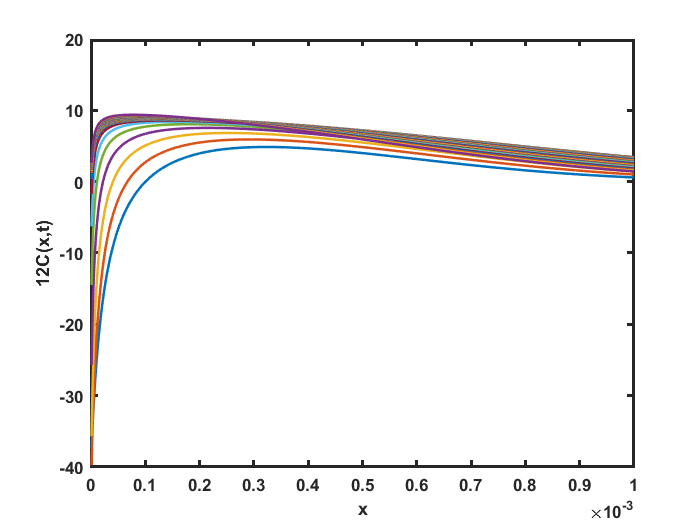

for i=5:50
    plot(x,q(:,i),"LineWidth",1.5)
    hold on
    h=gca;
    %set(gca, 'XDir','reverse')
    grid
    axis([0,0.001,-40,20]);
h.YLimMode='manual';
h.FontSize=10;
h.FontWeight="bold";
h.LineWidth=1.8;
xlabel('x');
ylabel('12C(x,t)');  
    %title(sprintf("Time:%d",t(i)))
end
hold off

oldmod=q(:,10)

oldmod =    -6.2726
   -4.0370
   -2.3631
   -1.0628
   -0.0237
    0.8257
    1.5330
    2.1311
    2.6434
    3.0871
